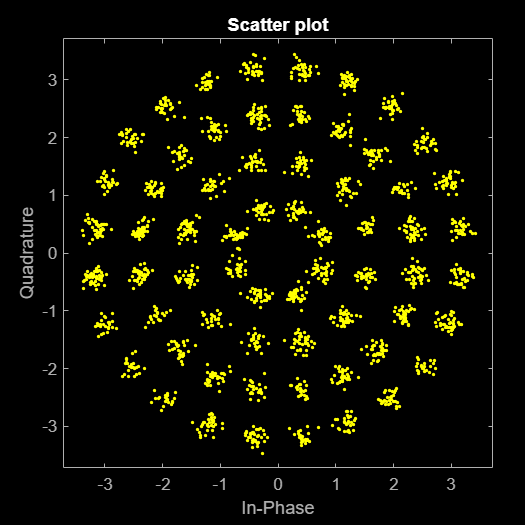

M = [8 12 20 24];
radii = [0.8 1.6 2.4 3.2];
bitsPerSym = log2(sum(M));

l = 2000;
x = randi([0 1],l*bitsPerSym,1);
y = apskmod(x,M,radii,'InputType','bit','OutputDataType','single');
yrec = awgn(y,25,'measured');
scatterplot(yrec)

z = apskdemod(yrec,M,radii,'OutputType','bit');
x

x =      0
     1
     1
     1
     0
     1
     1
     1
     0
     0


z

z = 12000×1 single column vector
     0
     1
     1
     1
     0
     1
     1
     1
     0
     0


isequal(z,x)

ans = logical
   0


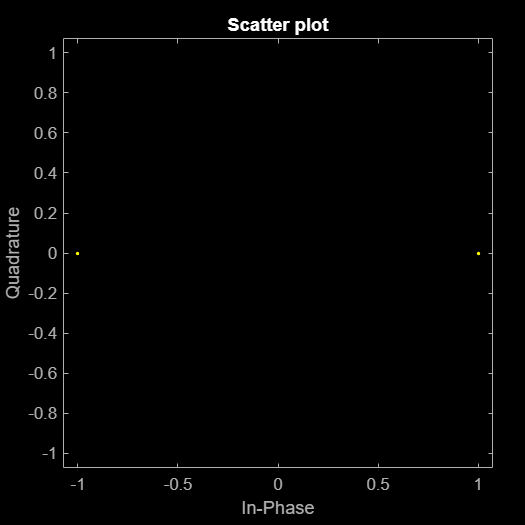

M = 2;
k = log2(M);
data = randi([0 1],1000*k,1);
txSig = qammod(data,M,'InputType','bit');
rxSig = awgn(txSig,25);
% cd = comm.ConstellationDiagram('ShowReferenceConstellation',false);
% cd(txSig)

scatterplot(txSig)